数据预处理

%电机失效数据
t = out.n3.Time;
h1 = out.n3.Data(:,1);
h2 = out.n3.Data(:,2);
h3 = out.n3.Data(:,3);
%电机健康数据
h1_health = healthFlightData.n3.Data(:,1);
h2_health = healthFlightData.n3.Data(:,2);
h3_health = healthFlightData.n3.Data(:,3);

figure(1)


$$\mathbf{n}_{3} = \left[
\begin{array}{ccc}
h_{1}&h_{2}&h_{3}\\
\end{array}
\right]^{\text{T}}$$


 这里绘制$h_1$

gh1 = subplot(8,1,[1 2]);

plot(t,h1,'LineWidth',2,'Color',[0 0.4470 0.7410]);
hold on
plot(t,h1_health,'LineWidth',2,'Color',[0.8500 0.3250 0.0980]);

xlabel('Time(s)')
ylabel('$h_{1}$',"Interpreter","latex")

set(gh1,'XGrid','on','YGrid','off');

这里绘制$h_2$

gh2 = subplot(8,1,[4 5]);

plot(t,h2,'LineWidth',2,'Color',[0 0.4470 0.7410]);
hold on
plot(t,h2_health,'LineWidth',2,'Color',[0.8500 0.3250 0.0980]);

xlabel('Time(s)')
ylabel('$h_{2}$',"Interpreter","latex")
% ylim([-0.05 0.05])
set(gh2,'XGrid','on','YGrid','off');

这里绘制$h_3$

gh3 = subplot(8,1,[7 8]);

plot(t,h3,'LineWidth',2,'Color',[0 0.4470 0.7410]);
hold on
plot(t,h3_health,'LineWidth',2,'Color',[0.8500 0.3250 0.0980]);

xlabel('Time(s)')
ylabel('$h_{3}$',"Interpreter","latex")
% ylim([0.999 1])

legend('One Motor Fail','Health','Location',"best")
legend('Box',"off")
set(gh3,'XGrid','on','YGrid','off');

标记

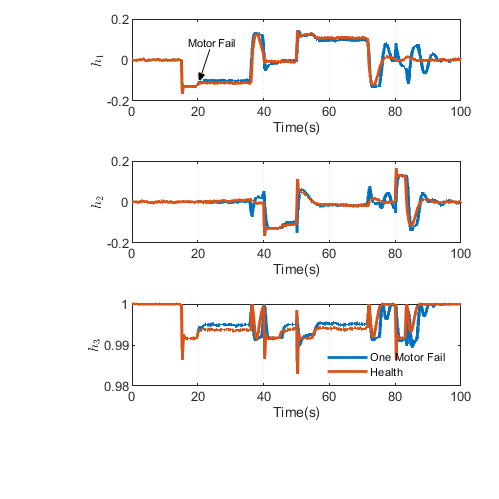

textarrow1 = annotation('textarrow',[0.42 0.40],[0.90 0.84],'String','Motor Fail');
textarrow1.FontSize = 8;
textarrow1.LineWidth = 0.1;
textarrow1.HeadLength = 5;
textarrow1.HeadWidth = 5;

% textarrow2 = annotation('textarrow',[0.75 0.8],[0.84 0.87],'String','Reach Target');
% textarrow2.FontSize = 8;
% textarrow2.LineWidth = 0.1;
% textarrow2.HeadLength = 5;
% textarrow2.HeadWidth = 5;